## Read the image:

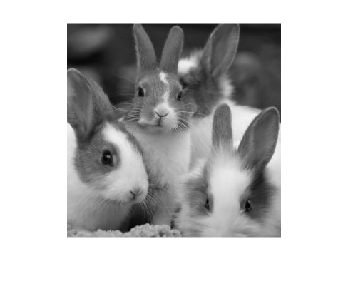

clear
clc

% 1. Read the image:
% I = imread('cameraman.tif');
original_img = imread('rabbit.jpg');
original_img = rgb2gray(original_img);
imwrite(original_img, 'rabbit_gray.jpeg'); % Save the image
imshow(original_img)

[R_img,C_img] = size(original_img); % to keep the size of the original image

padded_img = pad(original_img);   % check inside the function if the size 
                                  %of the image is divisable by 8, otherwise pad 
[R,C] = size(padded_img);  

## Table 1:

### Encoder: 

Table = QuantizationTable(1); % Using low quantization Table 
out_imge = [];

% Divide the image into blocks of 8x8 pixels:
for r = 1 : 7 : R-7
    for c = 1 : 7 : C-7
    block1 = padded_img(r:r+7,c:c+7);
    DCT_out = DCT(block1);    %2.Perform DCT on each block
    quantize_out = round(DCT_out./Table);   %3.Perform the quantization step per 8x8 block 
    one_D = serpentine(quantize_out);   %4.Transform each block from 2-D into 1-D vector
    out_code = run_length(one_D);   %5.Use run-length encoding to compress the stream of zeros
    out_imge = [out_imge out_code];  
    end
end

%6.Use Huffman function to encode the final stream:
[encoded_file,dict] = Huffman_encoder(out_imge);
huffman_dict = dict;
huffman_dict(:,2) = cellfun(@num2str,huffman_dict(:,2),'UniformOutput',false)

huffman_dict = 314×2 cell array
    {[ 59]}    {'0  0  1  1  0  1  0  0  0  0  1'}
    {[  0]}    {'1  1'                           }
    {[  2]}    {'0  0  1  0'                     }
    {[  1]}    {'1  0'                           }
    {[ 60]}    {'0  0  1  1  0  1  0  1  0  1  1'}
    {[ 58]}    {'0  0  1  1  1  0  0  1  0  1  0'}
    {[ -2]}    {'0  0  0  0  0'                  }
    {[ -1]}    {'0  1  0'                        }
    {[ 55]}    {'0  0  0  1  0  0  0  0  1  0  0'}
    {[ -5]}    {'0  0  0  1  0  1  1'            }
    {[  3]}    {'0  0  0  1  1'                  }
    {[ 54]}    {'0  0  0  0  1  1  0  1  1  0'   }
    {[-12]}    {'0  1  1  1  1  0  1  1  0'      }
    {[ 52]}    {'0  1  1  0  1  1  1  1  1  1'   }
    {[-15]}    {'0  0  0  1  0  0  0  1  1  1'   }
    {[  4]}    {'0  1  1  0  0'                  }


% save the output stream into a binary file
compressed_file = fopen('encoded.bin','w'); 
fwrite(compressed_file,encoded_file);
fclose(compressed_file);


% Compression ratio (no.bits of the whole image/length of the transmitted file)
len_uncompressed_file = R*C*8;
len_encoded_file = length(encoded_file);
comp_ratio = len_uncompressed_file/len_encoded_file

comp_ratio = 3.5027

### Decoder:

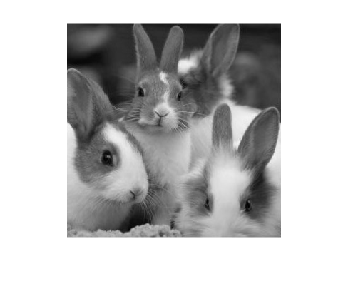

%7.Use Huffman decoder to decode the Huffman encoded stream:
file_ID = fopen('encoded.bin');
compressed_file_rd = fread(file_ID)';
decode_code = huffmandeco(compressed_file_rd,dict);

out_code = run_length_decoder(decode_code); %8.Perform run-length decoding

%9.Transform the 1-D vector into groups of 8x8 matrices:
I_rec = zeros(R,C);
i = 1;
for r = 1 : 7 : R - 7
    for c = 1 : 7 : C-7
        if i + 63 <= length(out_code)
            one_D = out_code(i:i+63);
            blockd1 = reverse_serpentine(one_D);
            blockd2 = blockd1.*Table;  %10.Multiply each group by the quantization tables
            blockd3 = IDCT(blockd2);  %11.Perform IDCT 
            I_rec(r :r + 7 , c : c + 7) = blockd3;  %12.Combine each block into a single image
            i = i + 64;
        end 
    end
end

I_rec = uint8(I_rec);
I_rec_crop= I_rec(1:R_img, 1:C_img); % cropping the image:
imwrite(I_rec_crop, 'decoded_img_table1.jpeg'); % Save the image
imshow(I_rec_crop)

% Absolute mean error to calculate quantitative
% measure of the image quality after compression:

n = R_img*C_img;
abs_error= sum(abs((I_rec_crop-original_img)),'all')/n

abs_error = 0.5931

## Table 2:

### Encoder: 

Table = QuantizationTable(2); % Using low quantization Table 
out_imge = [];

% Divide the image into blocks of 8x8 pixels:
for r = 1 : 7 : R-7
    for c = 1 : 7 : C-7
    block1 = padded_img(r:r+7,c:c+7);
    DCT_out = DCT(block1);    %2.Perform DCT on each block
    quantize_out = round(DCT_out./Table);   %3.Perform the quantization step per 8x8 block 
    one_D = serpentine(quantize_out);   %4.Transform each block from 2-D into 1-D vector
    out_code = run_length(one_D);   %5.Use run-length encoding to compress the stream of zeros
    out_imge = [out_imge out_code];  
    end
end

%6.Use Huffman function to encode the final stream:
[encoded_file,dict] = Huffman_encoder(out_imge);
huffman_dict = dict;
huffman_dict(:,2) = cellfun(@num2str,huffman_dict(:,2),'UniformOutput',false)

huffman_dict = 272×2 cell array
    {[59]}    {'1  1  1  0  1  1'      }
    {[ 0]}    {'1  0'                  }
    {[63]}    {'1  1  1  1  0  1  1  0'}
    {[58]}    {'0  0  1  1  0  0  1'   }
    {[ 1]}    {'0  0  0'               }
    {[-1]}    {'0  1  1'               }
    {[61]}    {'0  0  1  0  0  0'      }
    {[55]}    {'0  0  1  0  1  1'      }
    {[-3]}    {'1  1  1  1  1'         }
    {[54]}    {'1  1  0  0  1  1  0  1'}
    {[-6]}    {'1  1  1  0  0  0  0'   }
    {[52]}    {'1  1  1  0  0  0  1  0'}
    {[-7]}    {'0  1  0  0  0  0  0  1'}
    {[-8]}    {'1  1  1  1  0  1  1  1'}
    {[60]}    {'1  1  0  0  0  0  0  1'}
    {[-2]}    {'0  0  1  1  1'         }


% save the output stream into a binary file
compressed_file = fopen('encoded.bin','w'); 
fwrite(compressed_file,encoded_file);
fclose(compressed_file);


% Compression ratio (no.bits of the whole image/length of the transmitted file)
len_uncompressed_file = R*C*8;
len_encoded_file = length(encoded_file);
comp_ratio = len_uncompressed_file/len_encoded_file

comp_ratio = 8.8590

### Decoder:

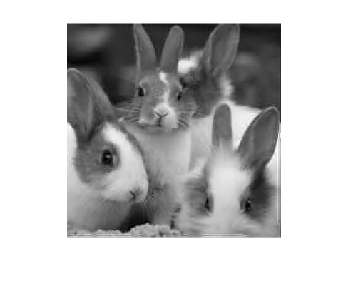

%7.Use Huffman decoder to decode the Huffman encoded stream:
file_ID = fopen('encoded.bin');
compressed_file_rd = fread(file_ID)';
decode_code = huffmandeco(compressed_file_rd,dict);

out_code = run_length_decoder(decode_code); %8.Perform run-length decoding

%9.Transform the 1-D vector into groups of 8x8 matrices:
I_rec = zeros(R,C);
i = 1;
for r = 1 : 7 : R - 7
    for c = 1 : 7 : C-7
        if i + 63 <= length(out_code)
            one_D = out_code(i:i+63);
            blockd1 = reverse_serpentine(one_D);
            blockd2 = blockd1.*Table;  %10.Multiply each group by the quantization tables
            blockd3 = IDCT(blockd2);  %11.Perform IDCT 
            I_rec(r :r + 7 , c : c + 7) = blockd3;  %12.Combine each block into a single image
            i = i + 64;
        end 
    end
end

I_rec = uint8(I_rec);
I_rec_crop= I_rec(1:R_img, 1:C_img); % cropping the image:
imwrite(I_rec_crop, 'decoded_img_table2.jpeg'); % Save the image
imshow(I_rec_crop)

% Absolute mean error to calculate quantitative
% measure of the image quality after compression:

n = R_img*C_img;
abs_error= sum(abs((I_rec_crop-original_img)),'all')/n

abs_error = 1.5941

### Comments:

- Comparing qualitatively on the compressed images versus the original image for quantization table 1 is same as seen here in the live editor, but in zooming the images, the compressed image of table 2 seems more blurred than that of table 1. 

- Using table 2 gives higher compression ratio and it doesn't make a huge difference in quality of the images than of table 1 according to the absolute mean error.